# Chapter 5: Gettin in on the action

Alright time to get this contributed back to the project!

Navigate so that the project is focused and click the commit button in the toolstrip to commit our changes.

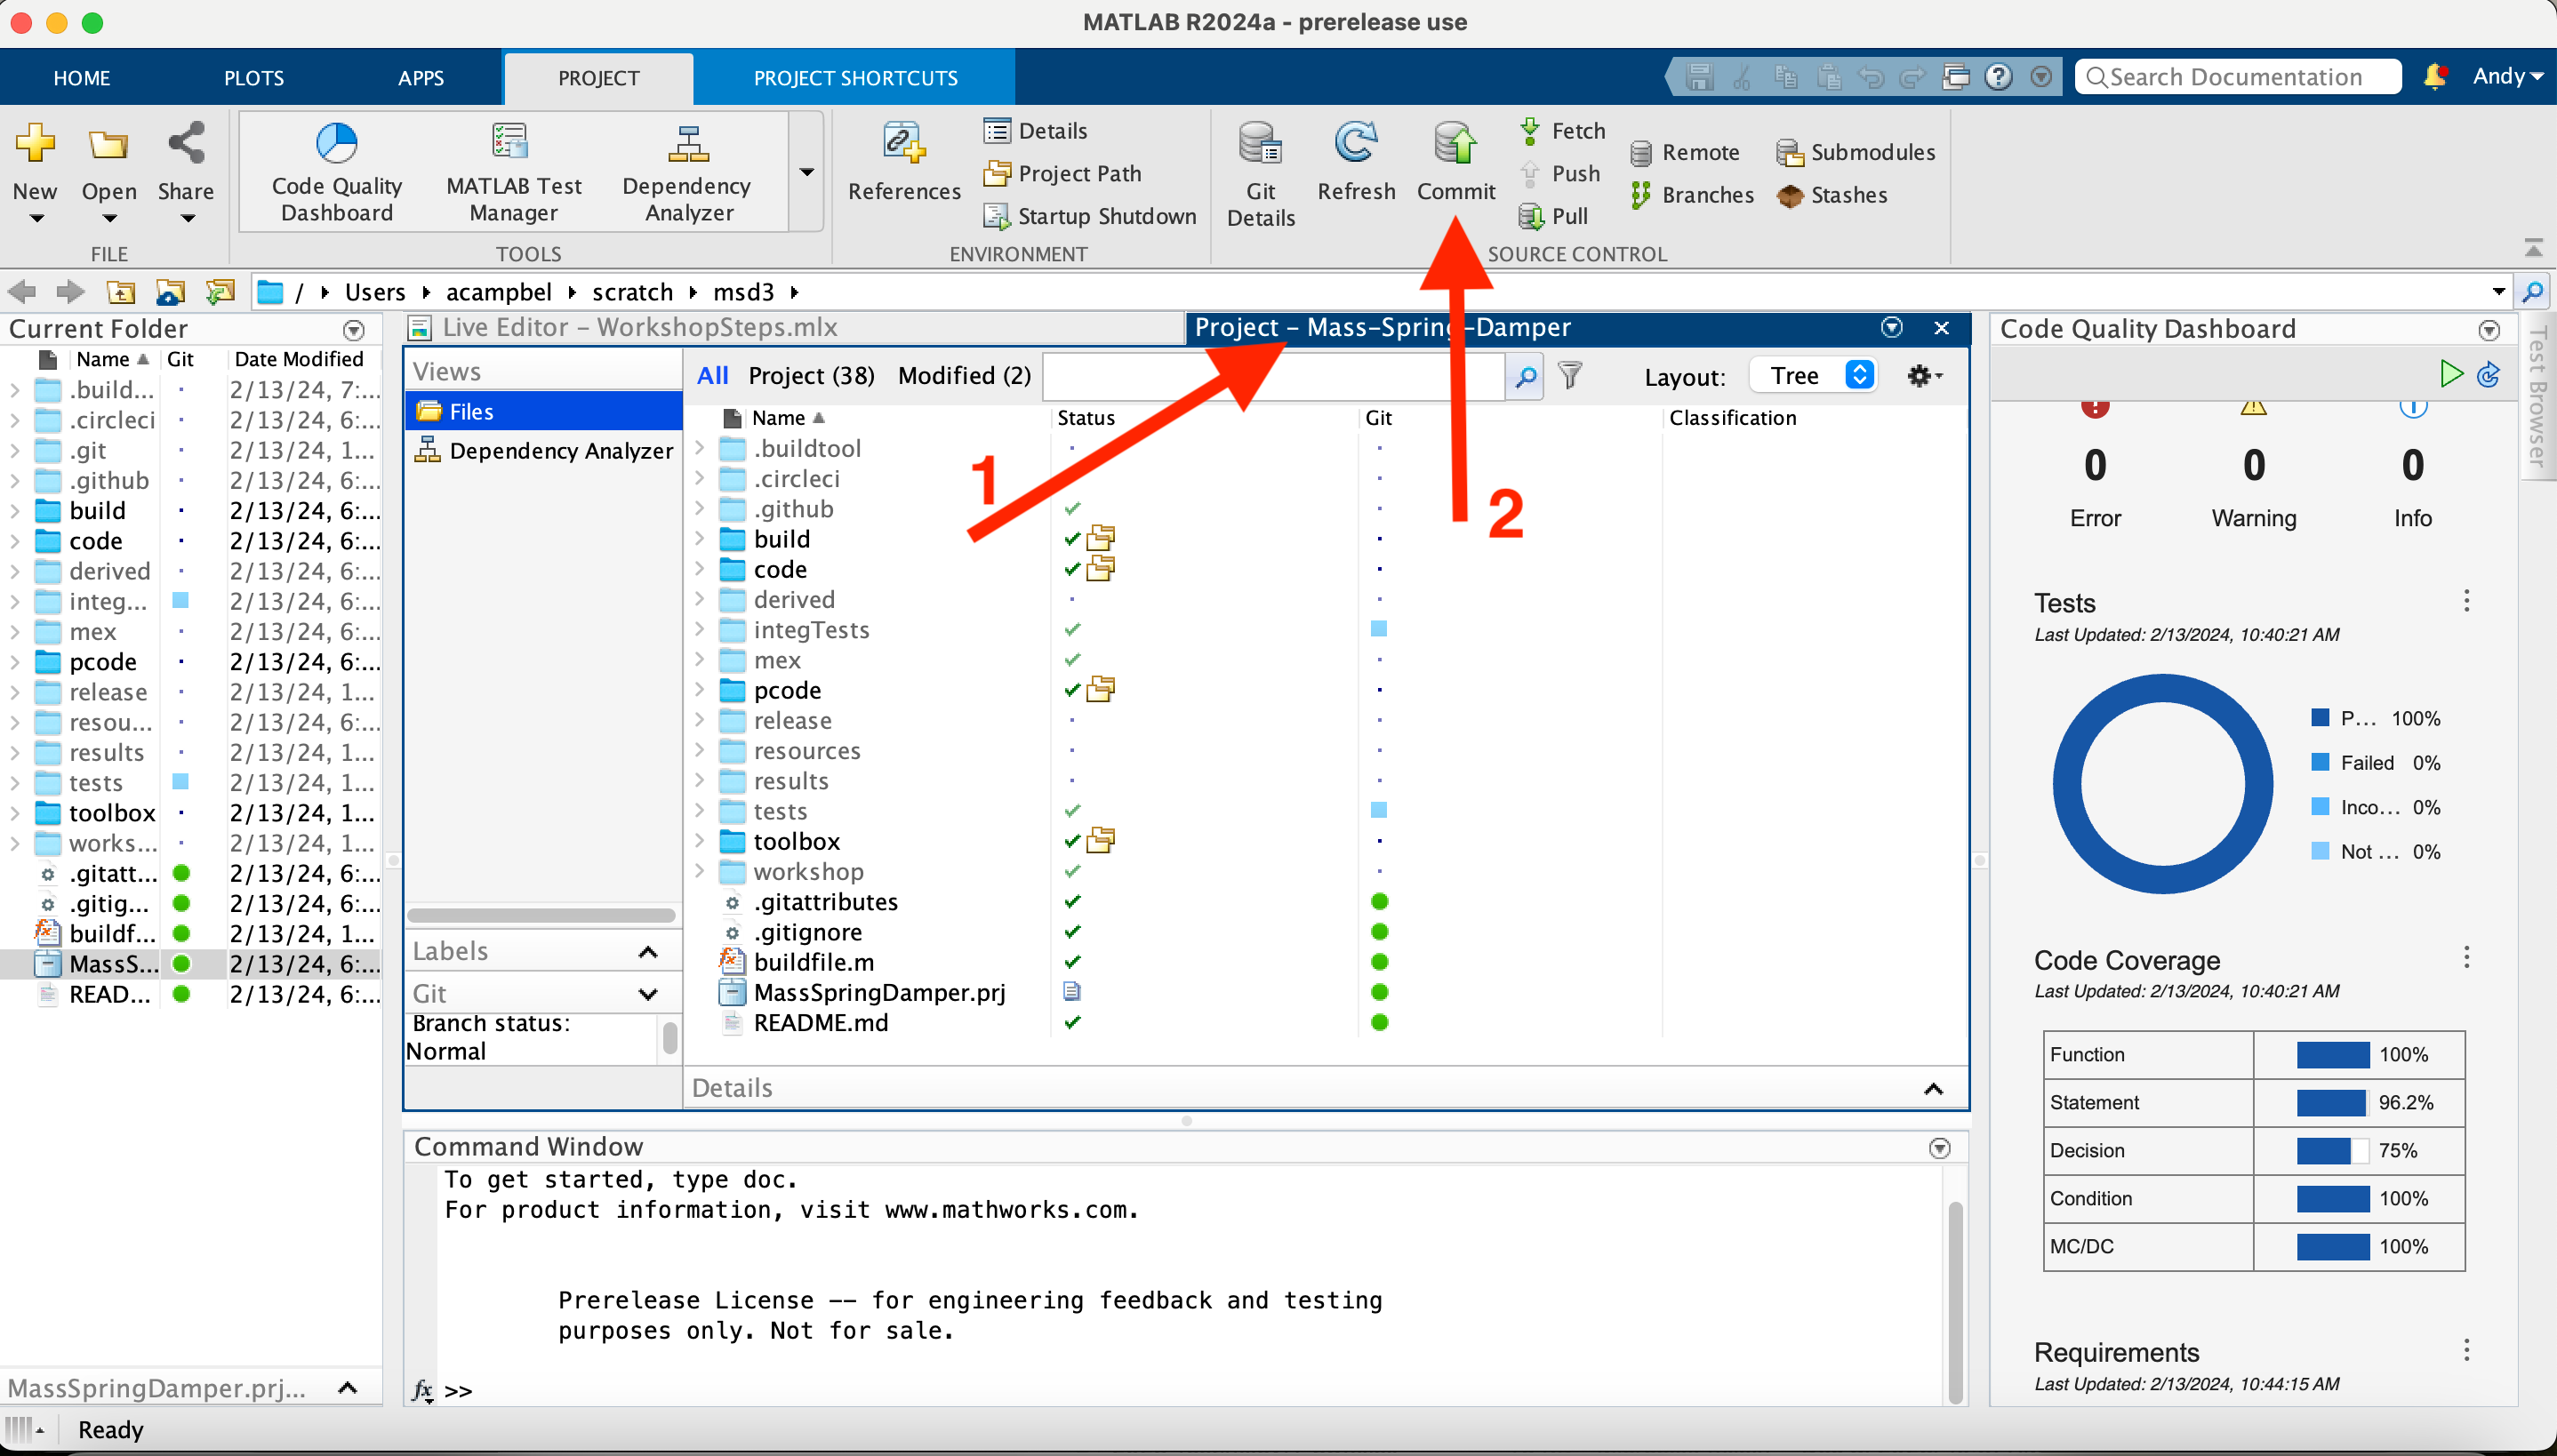

...and in a nice commit message ...

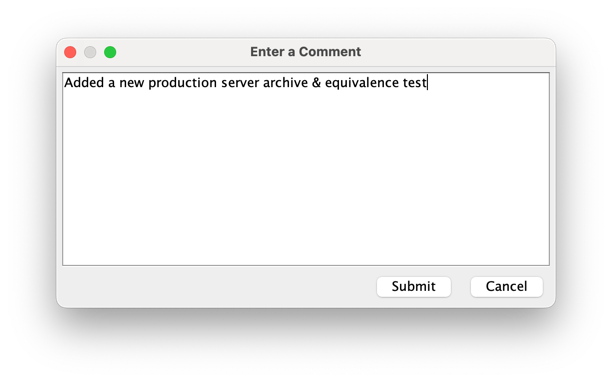

...and then push!

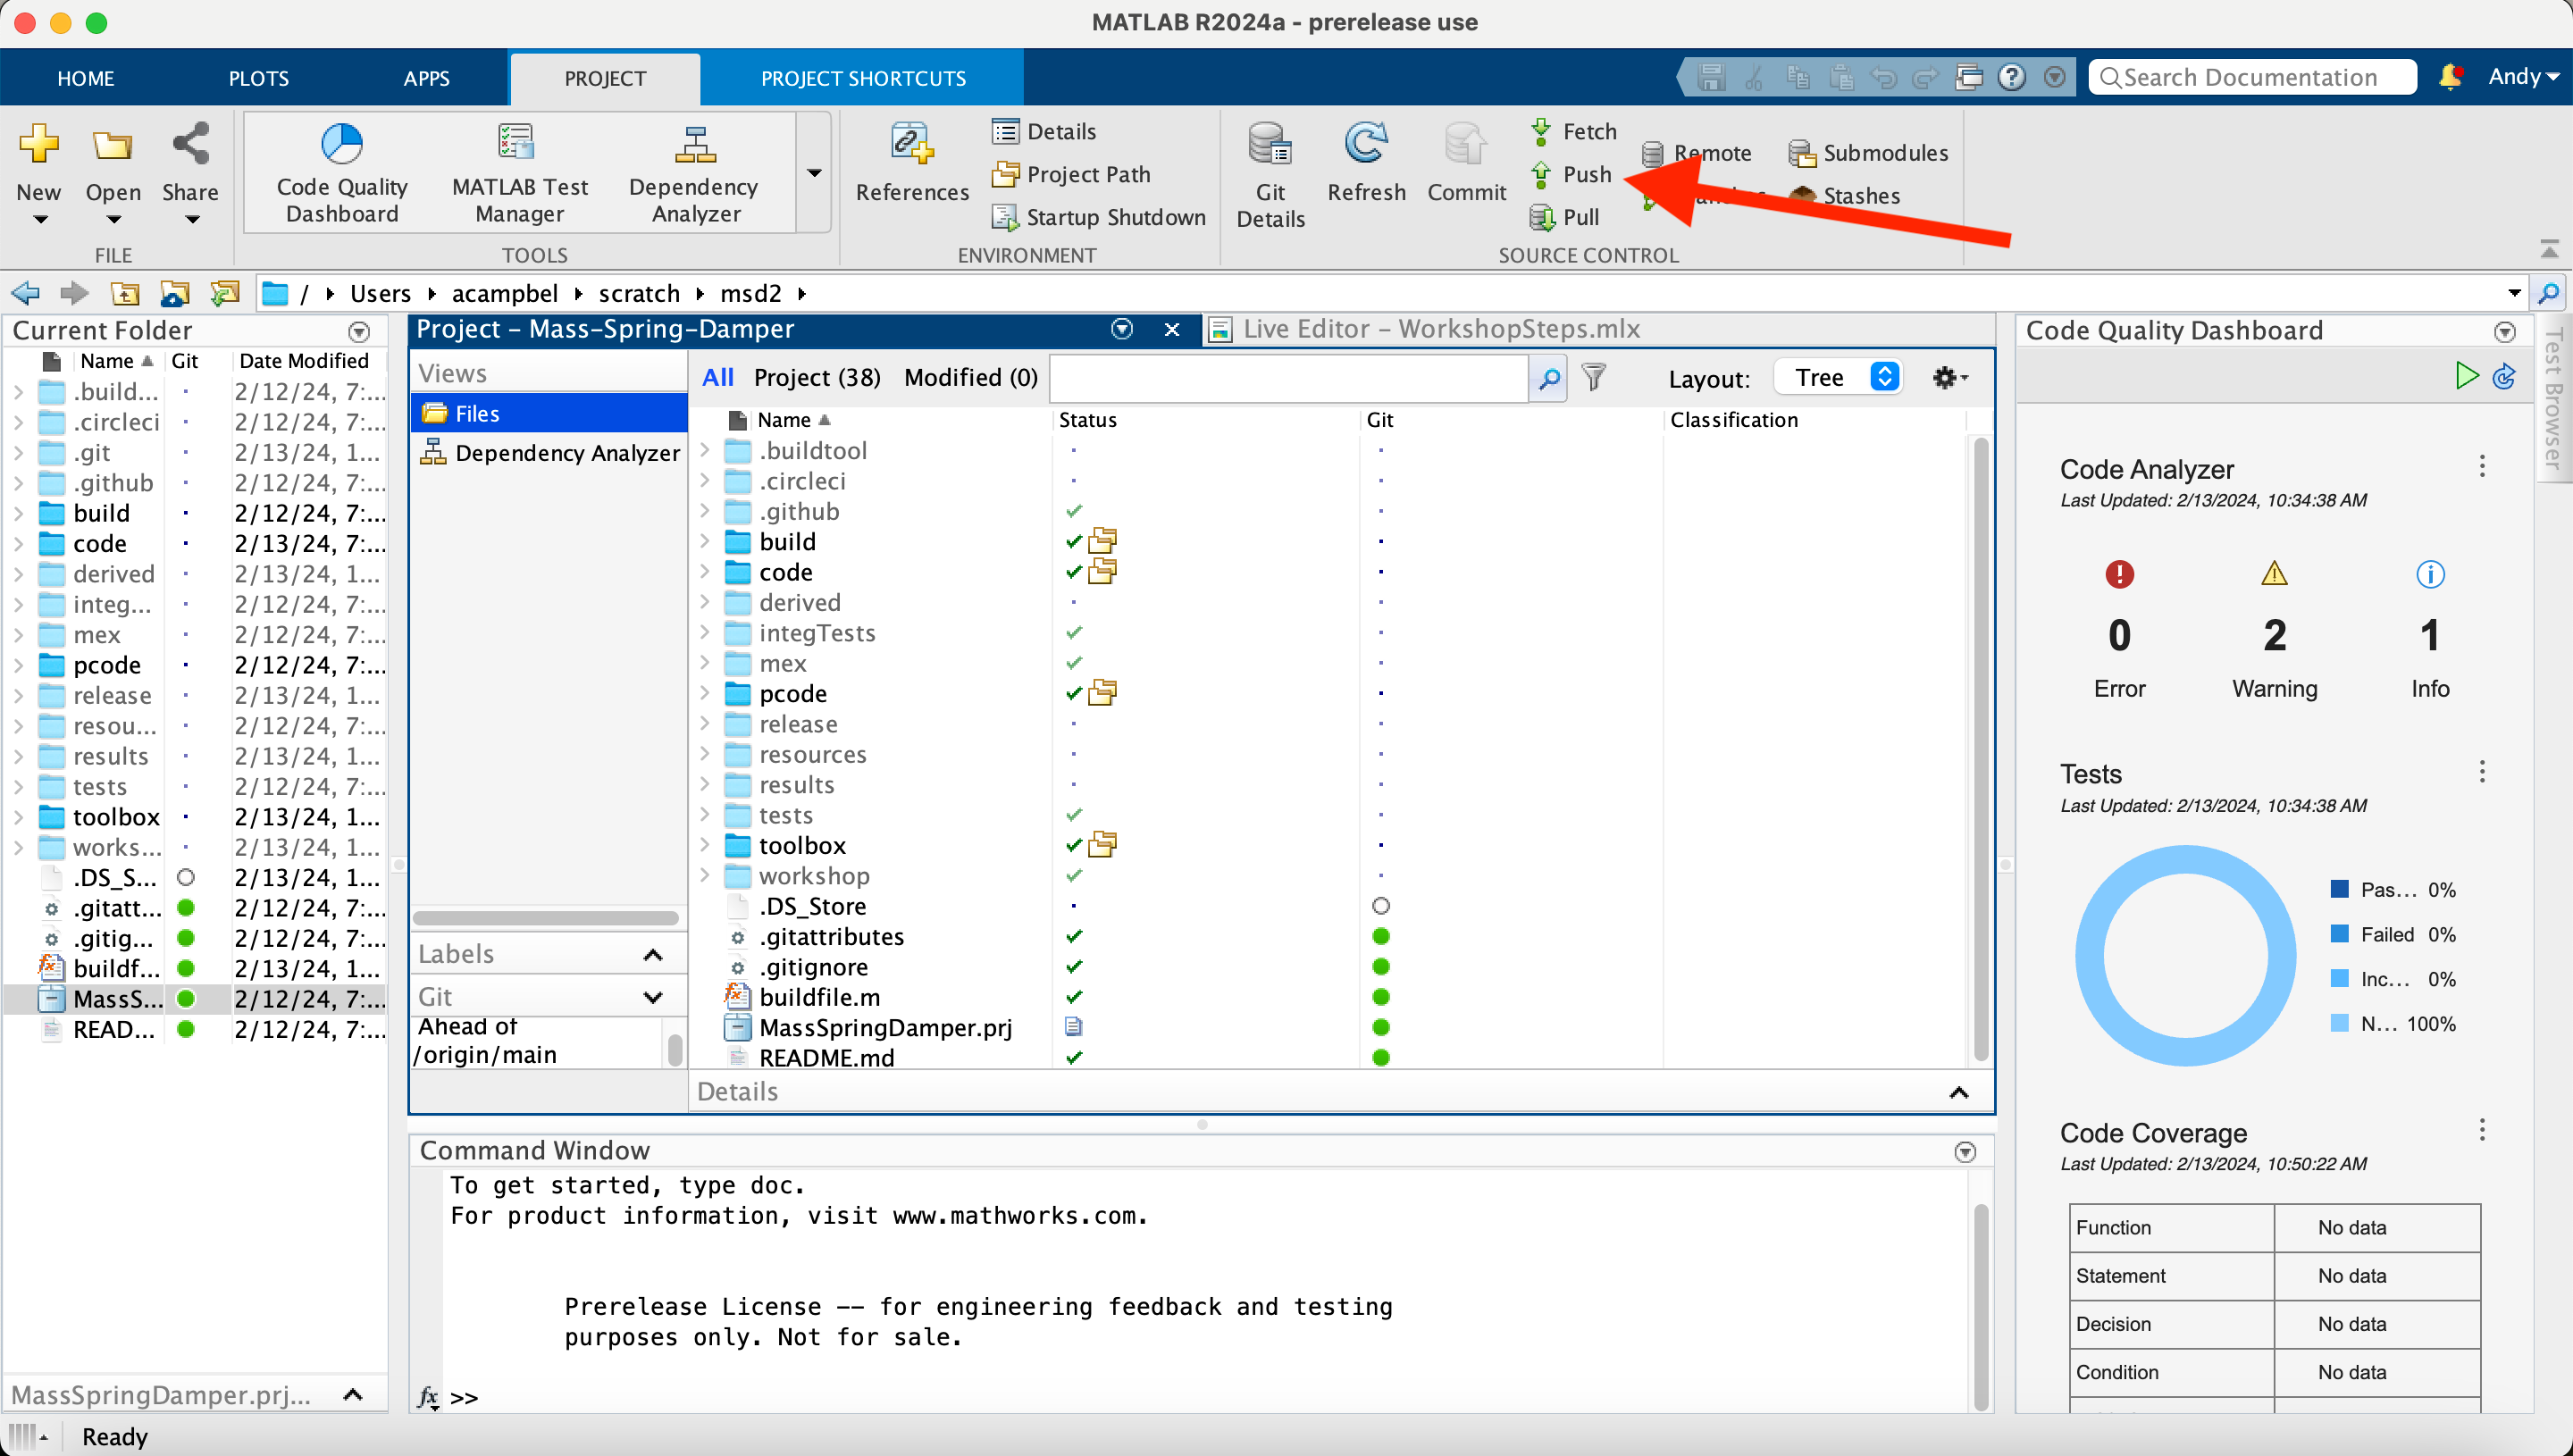

Now we can see the GitHub Actions going. Go back to your forked repository in your web browser. You will see your commit message at the top of your code listing along with an orange dot. This orange dot is indicating progress with your build. To see what is happening, click the Actions tab.

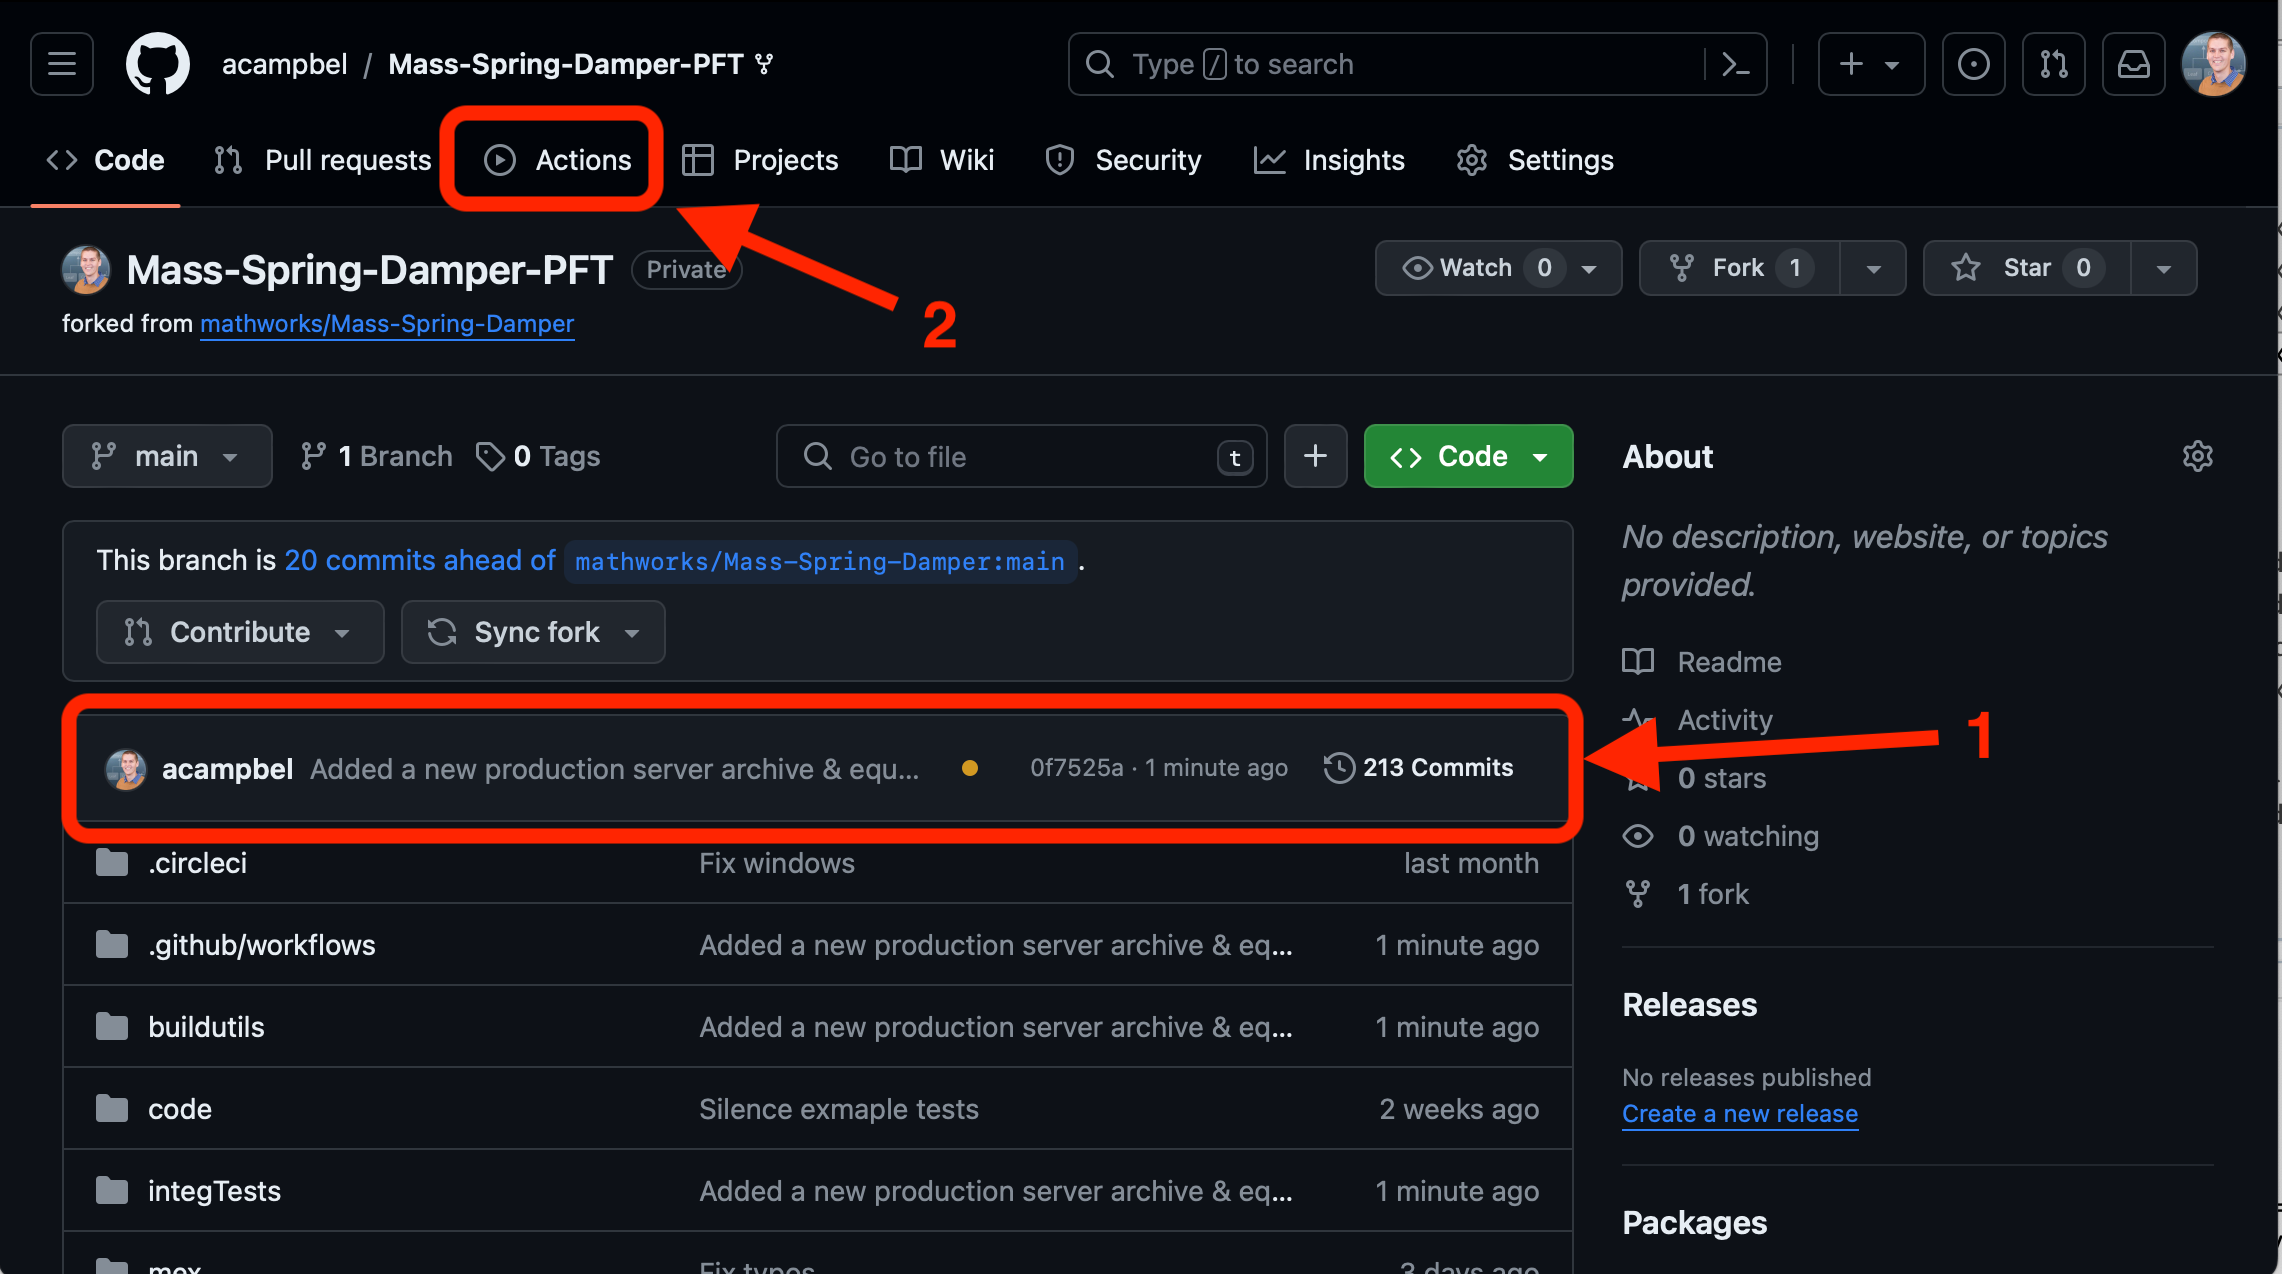

Here your job is running at the top of the list. Click through that job to see more of what is going on:

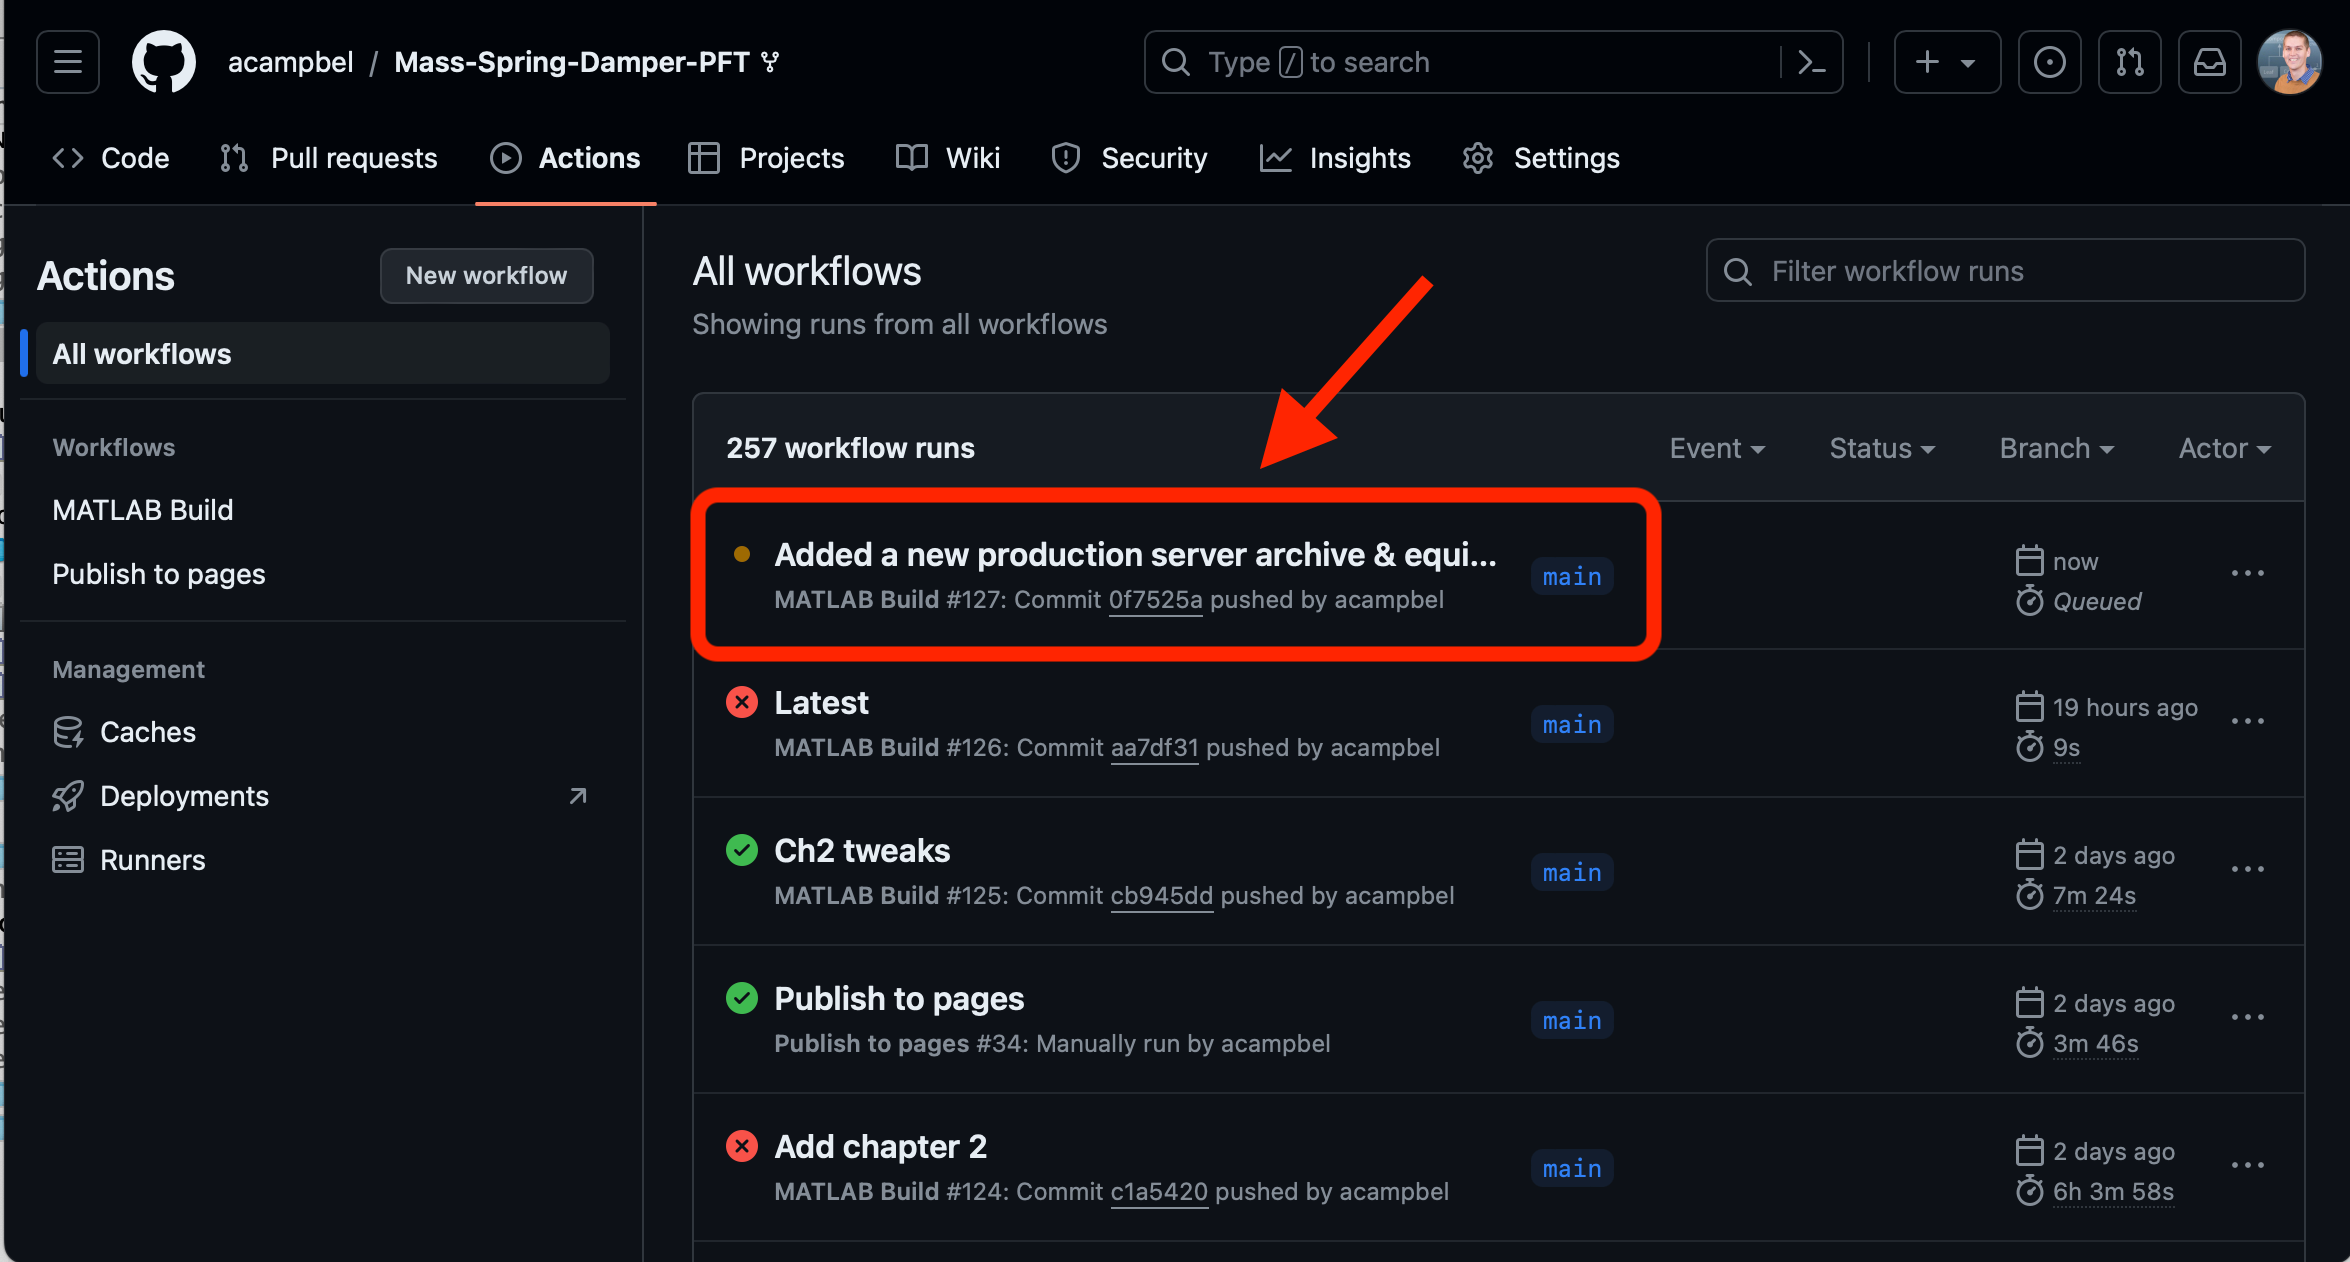

This will bring you to the Job Summary page. Here you can see that GitHub has spun up 3 machines for you for each platform. You don't need to worry about how it is orchestrated. You don't need to create and manage a Docker image. GitHub manages the infrastructure for you and the `matlab-actions `for GitHub take care of getting MATLAB on the machines that are they spin up. Taking a look at one of those jobs you can see that the setup process took about 1 minute and half (once cached), and you can expand the tree to observe the build:

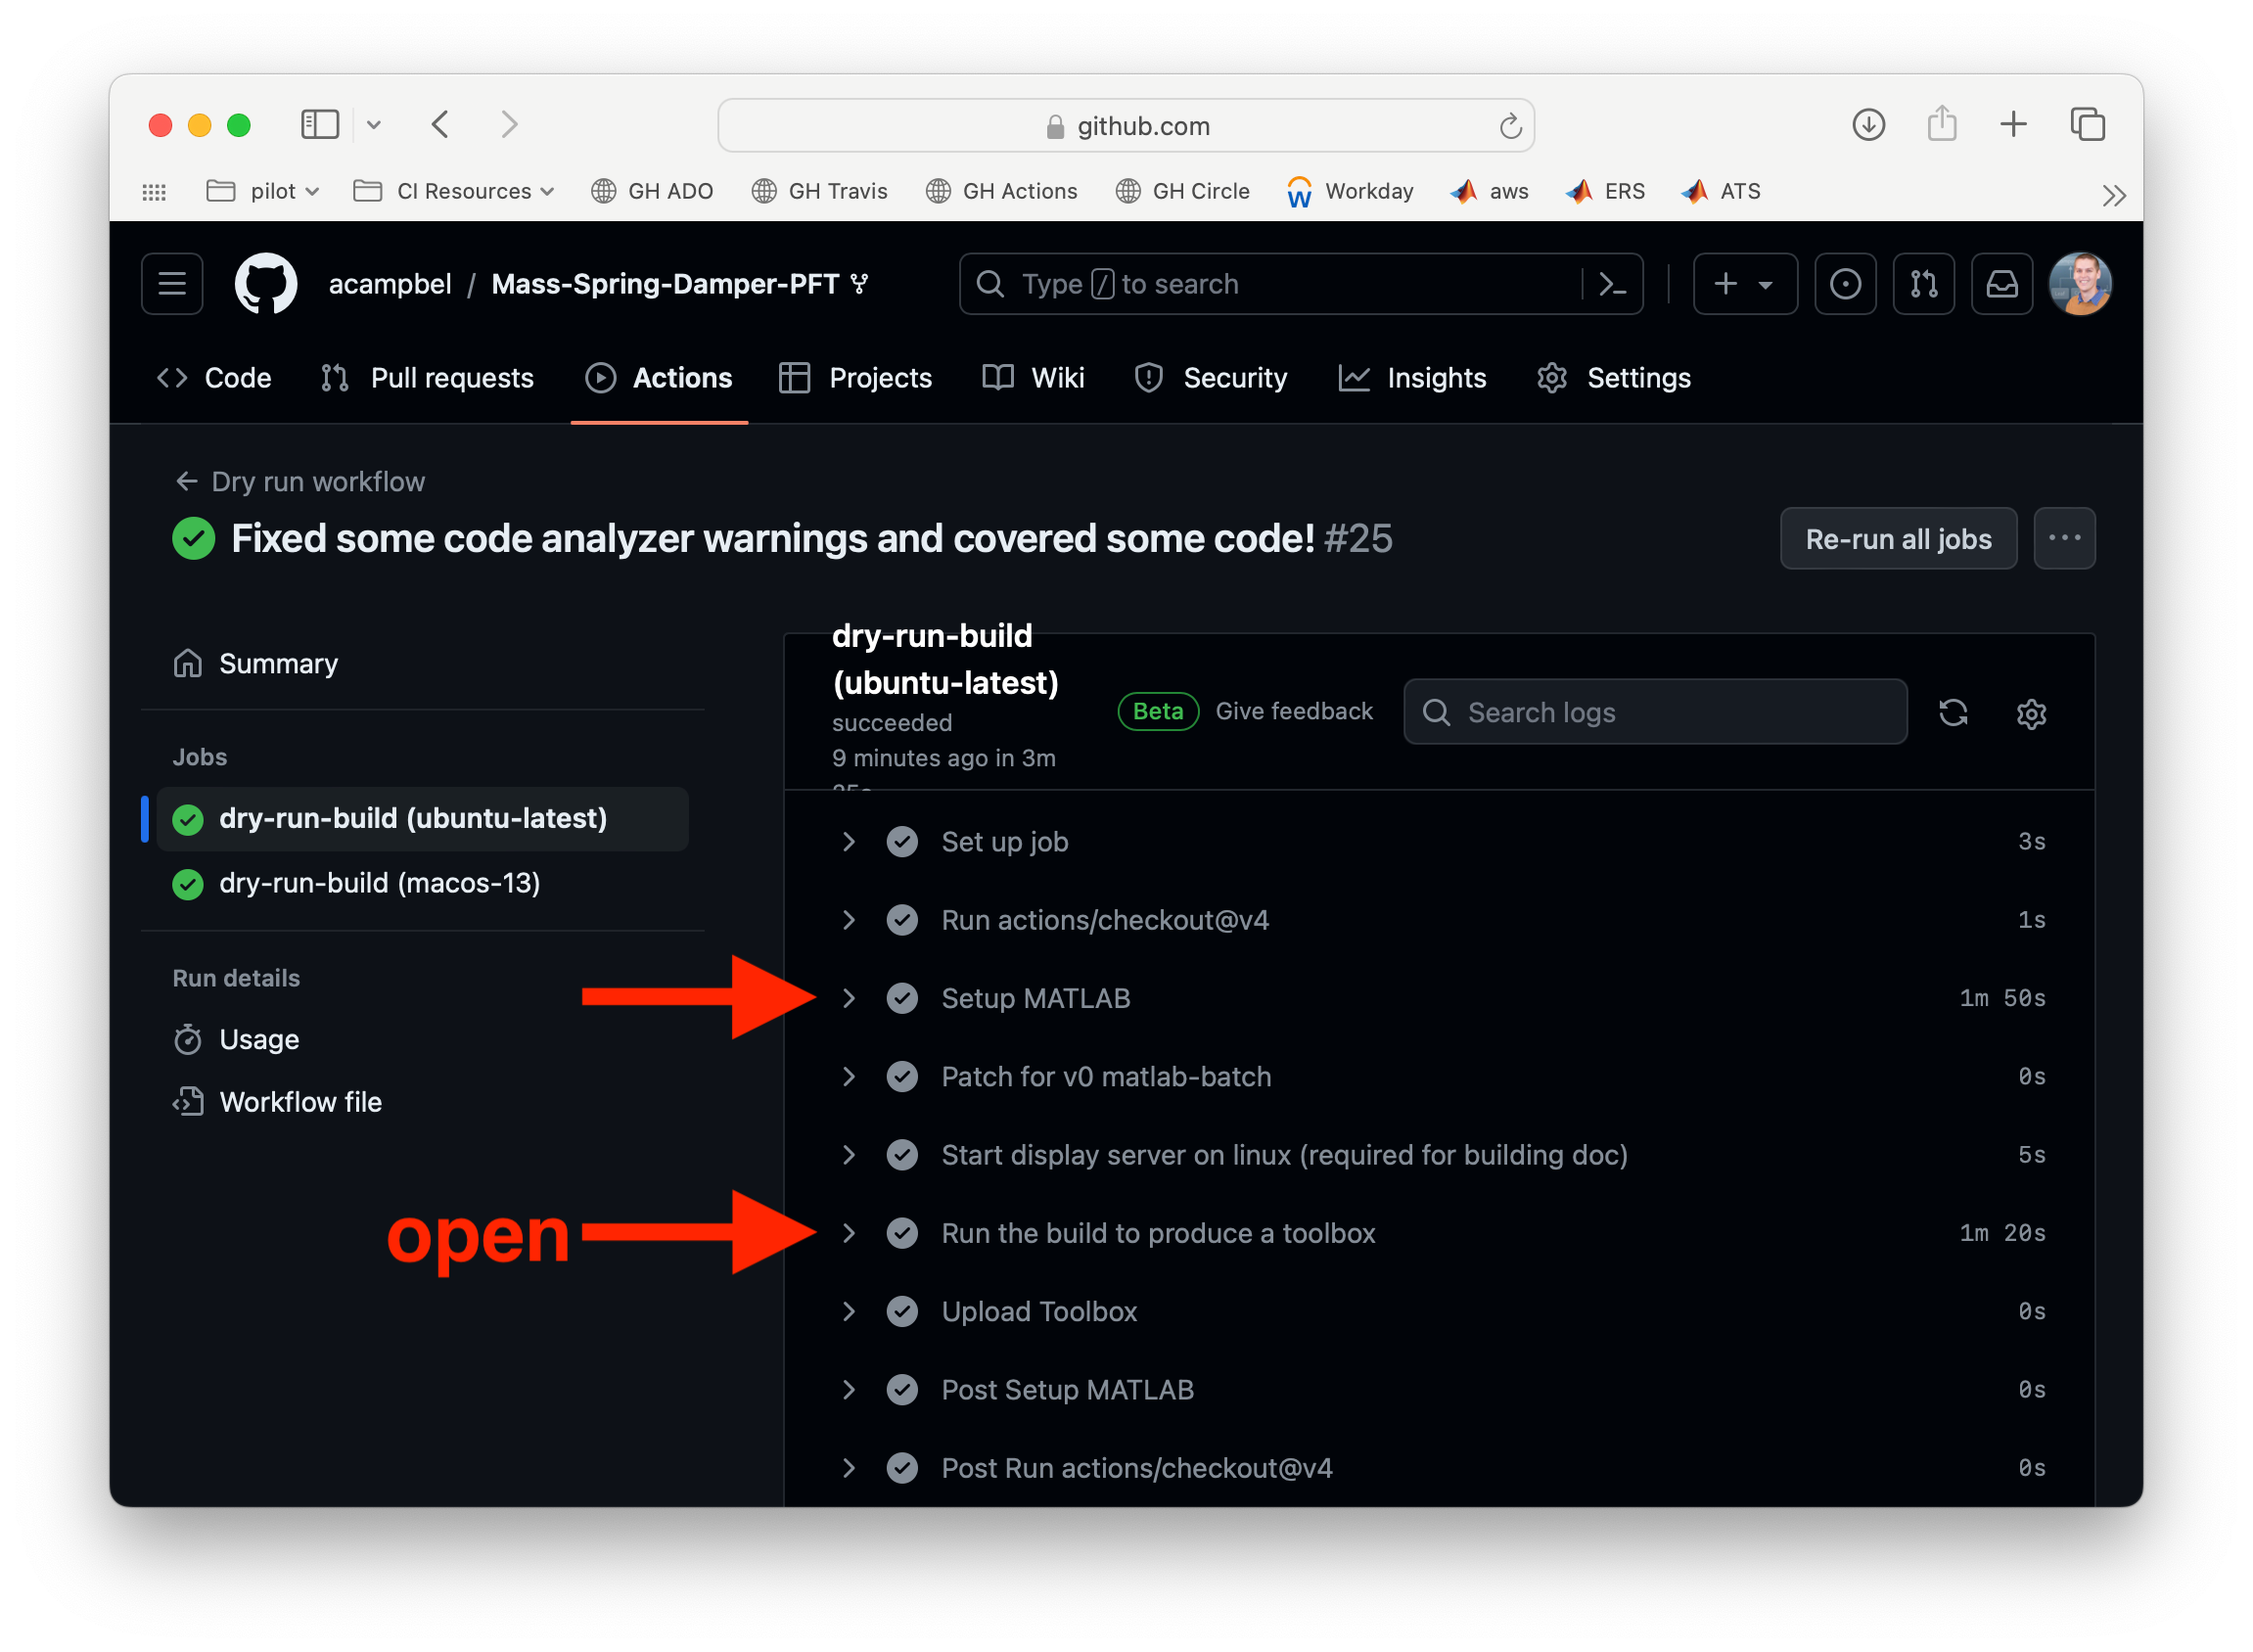

The build should look familiar! It should look just like what we ran as part of our local build process. And that's because it is! Using the build framework both locally and in CI enable you to develop locally in the same way the build occurs on the CI system. What is different here is that it is going through that process on multiple platforms simultaneously. For generating toolboxes, this is particularly useful as you need to build MEX files on all platforms you want to support with the toolbox.

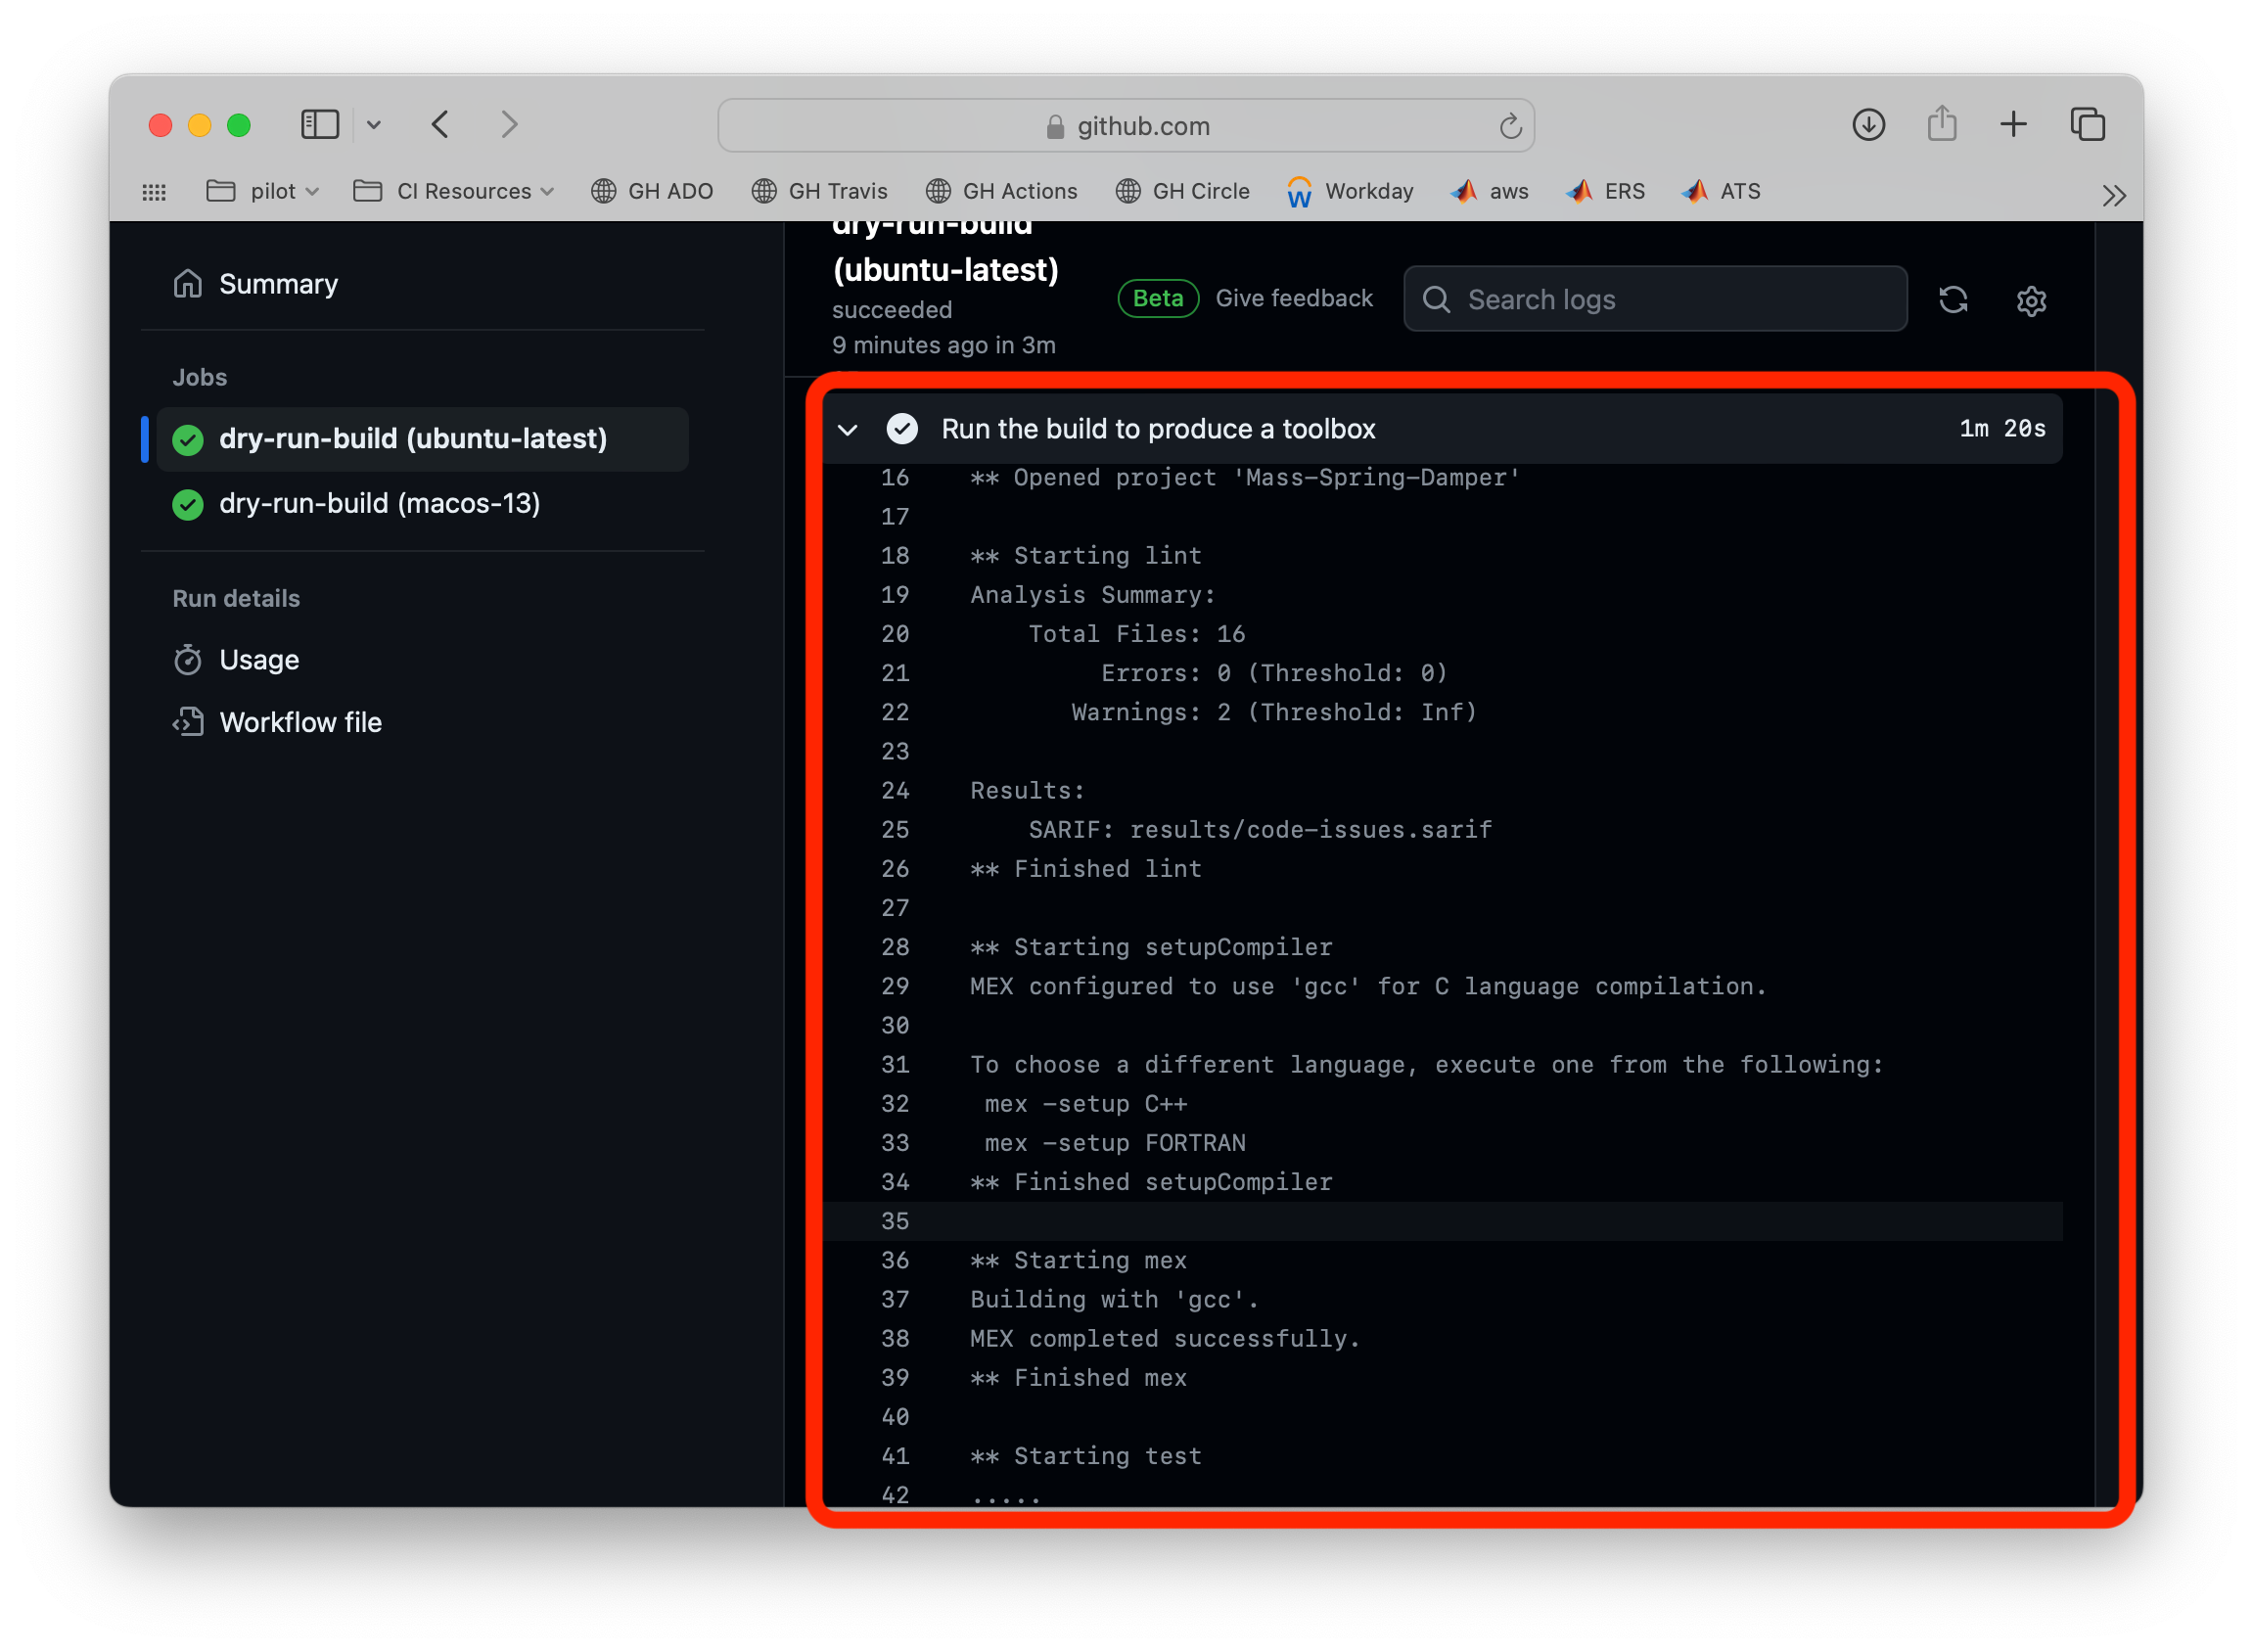

This build is building mex files on Linux, Windows, and Mac and then running unit tests on each platform by simply calling `buildtool test`. Once that is done, it downloads all of the generated artifacts (mex files and other artifacts like test results etc) on a new machine which does the release process for us (by calling `buildtool release`). Notice that even this CI build process is benefiting from incremental build.

This is all super cool, but there's an elephant (missing) in the room! The CI/CD is not actually generating our ctf and running our equivalence tests. This is because we need to add it to our GitHub Actions config!

Open up config file that defines how the GitHub Actions should build by opening the `.github/workflows/matlab-ci.yml` file.

openFile .github/workflows/matlab-ci.yml 100

This yaml configuration declares the steps to run in the CI/CD process on GitHub Actions. It leverages our extensions (the [`matlab-actions`](https://github.com/matlab-actions)) to simplify the MATLAB specific steps required. You can see in this file how everything we just observed is defined in a declarative manner. Note there are similar extensions provided for other platforms like Azure DevOps and CircleCI.

openFile .github/workflows/matlab-ci.yml 100

Navigate to line 100 and uncomment from there until the end of the file. Note, indenting and whitespace is important in this YAML file, so I recommend selecting these line sin the MATLAB editor, right clicking, and selecting "**Uncomment**". 

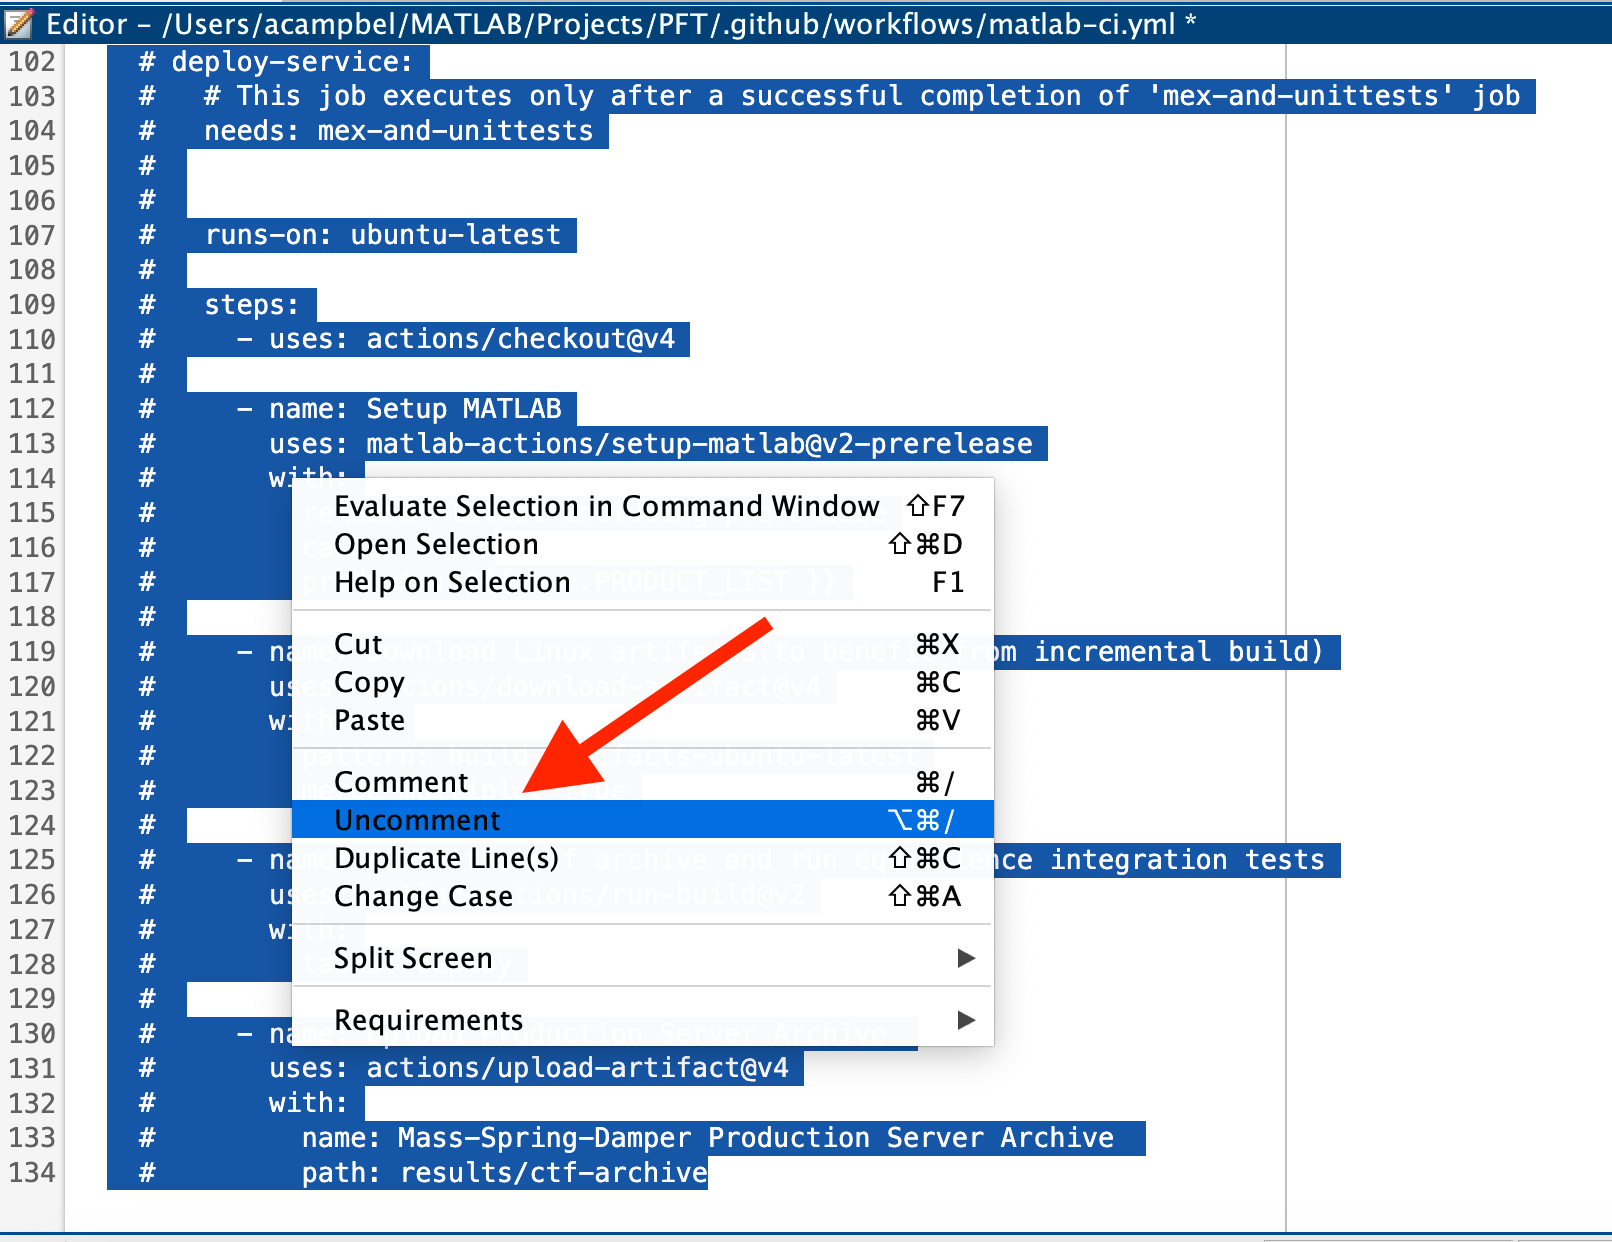

This section adds a new job to our GitHub pipeline. To do this:

showCode .github/workflows/matlab-ci.yml 102:104

102     deploy-service:
103       # This job executes only after a successful completion of 'mex-and-unittests' job
104       needs: mex-and-unittests


- Create a new job called `deploy-service` that requires `mex-and-unittests` job to run first. We don't want to deploy if our unit tests fail!

showCode .github/workflows/matlab-ci.yml 112:117

112         - name: Setup MATLAB
113           uses: matlab-actions/setup-matlab@v2-prerelease
114           with:
115             release: latest-including-prerelease
116             cache: true
117             products: ${{ env.PRODUCT_LIST }}


- Use the `matlab-actions/setup-matlab` action to set up MATLAB on the agent orchestrated by GitHub

showCode .github/workflows/matlab-ci.yml 119:123

119         - name: Download Linux artifacts(to benefit from incremental build)
120           uses: actions/download-artifact@v4
121           with:   
122             pattern: build-artifacts-ubuntu-latest
123             merge-multiple: true


- Download the build artifacts from the Linux unit test job. This prevents the need to run the unit tests again.

showCode .github/workflows/matlab-ci.yml 125:128

125         - name: Build the ctf archive and run equivalence integration tests
126           uses: matlab-actions/run-build@v2
127           with:
128             tasks: deploy


- Use the `matlab-actions/run-build` action to run our new `deploy` task!

showCode .github/workflows/matlab-ci.yml 130:134

130         - name: Upload Production Server Archive 
131           uses: actions/upload-artifact@v4
132           with:
133             name: Mass-Spring-Damper Production Server Archive 
134             path: results/ctf-archive


- Then upload the resulting artifact to GitHub

Now commit and push!

open Chapter_6

#### [Preface & TOC](matlab:open('index.html')) | [Chapter 6](matlab:open('Chapter_6.html'))